clear all
load 'D:\Jazmin\MultichannelDataTanks\HIP\October\HistogramsSpikesTable_MUA.mat';
load 'D:\Jazmin\MultichannelDataTanks\HIP\October\HistogramsSpikesTable.mat'; %The matrix obtained from the fuction ExtractMatFiles.m
BST = load('D:\Jazmin\MultichannelDataTanks\HIP\spiketable_KS4.mat');
BST_MUA = load('D:\Jazmin\MultichannelDataTanks\HIP\spiketableKS4_MUA.mat');
HistogramsSpikesTable_MUA = [HistogramsSpikesTable_MUA,BST_MUA.spiketable];
HistogramsSpikesTable = [HistogramsSpikesTable,BST.spiketable];
SignificanceWindowTableSpikes = [HistogramsSpikesTable_MUA;HistogramsSpikesTable];
% It is necesasry to either comment out the sections corresponding to
% Auditory, SSA-significant, DG or CA1, depending on what you want to plot.
% Created by Jazmin Sanchez 2025

% Load tungsted data
PSTH_CA1_Aud = load ('D:\Jazmin\MultichannelDataTanks\HIP\Spike Matrix\PSTH_CA1_Aud.mat');
PSTH_CA1_Sig = load ('D:\Jazmin\MultichannelDataTanks\HIP\Spike Matrix\PSTH_CA1_Sig.mat');
PSTH_DG_Aud = load ('D:\Jazmin\MultichannelDataTanks\HIP\Spike Matrix\PSTH_DG_Aud.mat');
PSTH_DG_Sig = load ('D:\Jazmin\MultichannelDataTanks\HIP\Spike Matrix\PSTH_DG_Sig.mat');


x1 = SignificanceWindowTableSpikes.histcenters(1,41);
x1_indx = 41;
x2 = SignificanceWindowTableSpikes.histcenters(1,200);
x2_indx = 200;

Path = 'D:\Jazmin\MultichannelDataTanks\HIP\CSI_Boottstrap.xlsx';
% Import table
HIP_Multi  = readtable(Path);
HIParray = table2array(HIP_Multi(:,["CSI","Rango_1","Rango_2"]));
% HIParray(any(isnan(HIParray), 2), :) = [];

load 'D:\Jazmin\MultichannelDataTanks\HIP\NormalizedIndexesTableMUA.mat';
load 'D:\Jazmin\MultichannelDataTanks\HIP\SignificanceWindowTableMUA.mat'; %The matrix obtained from the fuction ExtractMatFiles.m
load 'D:\Jazmin\MultichannelDataTanks\HIP\NormalizedIndexesTable.mat';
load 'D:\Jazmin\MultichannelDataTanks\HIP\SignificanceWindowTable.mat';

SignificanceWindowTableComplete = [SignificanceWindowTableMUA;SignificanceWindowTable];
NormalizedIndexesTable = [NormalizedIndexesTableMUA;NormalizedIndexesTable];

% Significance 
n= 1;
for i = 1: size(SignificanceWindowTableComplete,1)
    if (SignificanceWindowTableComplete.SignificanceDEV1(i,1) + SignificanceWindowTableComplete.SignificanceDEV2(i,1)) > 1
        SIscatterIndx(n,1)=i;
        n = n + 1;
    end
end

% Significance Strict
n= 1;
for i = 1: size(SignificanceWindowTable,1)
    if ((SignificanceWindowTable.SignificanceDEV1(i,1) + SignificanceWindowTable.SignificanceDEV2(i,1)) > 1) && ((SignificanceWindowTable.SignificanceSTD1(i,1) + SignificanceWindowTable.SignificanceSTD2(i,1)) > 1)
        SIscatterIndx_Strict(n,1)=i;
        n = n + 1;
    end
end

n=0;
for i = 1:size(SIscatterIndx_Strict,1)
    n=n+1;
    HIParrayAuditory(n,[1,2,3]) = HIParray(SIscatterIndx_Strict(i),:);
end


n=0;
m=0;
for i = 1:size(HIParrayAuditory,1)
    if HIParrayAuditory(i,2)<0 && HIParrayAuditory(i,3)>0
        n = n + 1;
        NonSignificant(n,1) = i;
    else
        m = m + 1;
        Significant(m,1) = i;
    end
end


for j = 1: size(NonSignificant,1)
    CSI_NonSignificant(j,1) = HIParrayAuditory(NonSignificant(j,1),1);
end

for k = 1: size(Significant,1)
    CSI_Significant(k,1) = HIParrayAuditory(Significant(k,1),1);
end

n=0;
for i = 1:size(SIscatterIndx,1)
    n=n+1;
    SignificanceWindowTableSpikesAuditory(n,:) = SignificanceWindowTableSpikes(SIscatterIndx(i),:);
end

for k = 1: size(NonSignificant,1)
    SignificanceWindowTableSpikesAuditorySig(k,:) = SignificanceWindowTableSpikesAuditory(NonSignificant(k,1),:);
end

% Auditory
for i = 1:size(SignificanceWindowTableSpikesAuditory,1)

STD_F1_F2(i,:) = (SignificanceWindowTableSpikesAuditory.histdatstd1(i,[80:119]) + SignificanceWindowTableSpikesAuditory.histdatstd2(i,[80:119]))./2;
DEV_F1_F2(i,:) = (SignificanceWindowTableSpikesAuditory.histdatdev1(i,[81:120]) + SignificanceWindowTableSpikesAuditory.histdatdev2(i,[81:120]))./2;
CTR_F1_F2(i,:) = (SignificanceWindowTableSpikesAuditory.histdatctr1ca(i,[81:120]) + SignificanceWindowTableSpikesAuditory.histdatctr2ca(i,[81:120]) + SignificanceWindowTableSpikesAuditory.histdatctr1cd(i,[81:120]) + SignificanceWindowTableSpikesAuditory.histdatctr2cd(i,[81:120]))./4;

N(i,:) = sqrt( (mean(DEV_F1_F2(i,:),"omitnan"))^2 + (mean(STD_F1_F2(i,:),"omitnan"))^2 + (mean(CTR_F1_F2(i,:),"omitnan"))^2);

STD_F1_F2(i,:) = STD_F1_F2(i,:)/N(i,:);
DEV_F1_F2(i,:) = DEV_F1_F2(i,:)/N(i,:);
CTR_F1_F2(i,:) = CTR_F1_F2(i,:)/N(i,:);


end

% %Significant
% for i = 1:size(SignificanceWindowTableSpikesAuditorySig,1)
% 
% STD_F1_F2(i,:) = (SignificanceWindowTableSpikesAuditorySig.histdatstd1(i,[80:119]) + SignificanceWindowTableSpikesAuditorySig.histdatstd2(i,[80:119]))./2;
% DEV_F1_F2(i,:) = (SignificanceWindowTableSpikesAuditorySig.histdatdev1(i,[81:120]) + SignificanceWindowTableSpikesAuditorySig.histdatdev2(i,[81:120]))./2;
% CTR_F1_F2(i,:) = (SignificanceWindowTableSpikesAuditorySig.histdatctr1ca(i,[81:120]) + SignificanceWindowTableSpikesAuditorySig.histdatctr2ca(i,[81:120]) + SignificanceWindowTableSpikesAuditorySig.histdatctr1cd(i,[81:120]) + SignificanceWindowTableSpikesAuditorySig.histdatctr2cd(i,[81:120]))./4;
% 
% N(i,:) = sqrt( (mean(DEV_F1_F2(i,:),"omitnan"))^2 + (mean(STD_F1_F2(i,:),"omitnan"))^2 + (mean(CTR_F1_F2(i,:),"omitnan"))^2);
% 
% STD_F1_F2(i,:) = STD_F1_F2(i,:)/N(i,:);
% DEV_F1_F2(i,:) = DEV_F1_F2(i,:)/N(i,:);
% CTR_F1_F2(i,:) = CTR_F1_F2(i,:)/N(i,:);
% 
% end

% % %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% CA1
SignificanceWindowTableSpikesAuditorySigCA1(1,:)=SignificanceWindowTableSpikesAuditorySig(6,:);
SignificanceWindowTableSpikesAuditorySigCA1(2,:)=SignificanceWindowTableSpikesAuditorySig(10,:);
SignificanceWindowTableSpikesAuditorySigCA1(3,:)=SignificanceWindowTableSpikesAuditorySig(14,:);
SignificanceWindowTableSpikesAuditorySigCA1(4,:)=SignificanceWindowTableSpikesAuditorySig(16,:);
SignificanceWindowTableSpikesAuditorySigCA1(5,:)=SignificanceWindowTableSpikesAuditorySig(18,:);
SignificanceWindowTableSpikesAuditorySig = [];
SignificanceWindowTableSpikesAuditorySig = SignificanceWindowTableSpikesAuditorySigCA1;

for i = 1:size(SignificanceWindowTableSpikesAuditorySig,1)

STD_F1_F2_CA1(i,:) = (SignificanceWindowTableSpikesAuditorySig.histdatstd1(i,[80:119]) + SignificanceWindowTableSpikesAuditorySig.histdatstd2(i,[80:119]))./2;
DEV_F1_F2_CA1(i,:) = (SignificanceWindowTableSpikesAuditorySig.histdatdev1(i,[81:120]) + SignificanceWindowTableSpikesAuditorySig.histdatdev2(i,[81:120]))./2;
CTR_F1_F2_CA1(i,:) = (SignificanceWindowTableSpikesAuditorySig.histdatctr1ca(i,[81:120]) + SignificanceWindowTableSpikesAuditorySig.histdatctr2ca(i,[81:120]) + SignificanceWindowTableSpikesAuditorySig.histdatctr1cd(i,[81:120]) + SignificanceWindowTableSpikesAuditorySig.histdatctr2cd(i,[81:120]))./4;
STD_F1_F2_After_CA1(i,:) = (SignificanceWindowTableSpikesAuditorySig.histdatdev1(i,[121:160]) + SignificanceWindowTableSpikesAuditorySig.histdatdev2(i,[121:160]))./2;

N(i,:) = sqrt( (mean(DEV_F1_F2_CA1(i,:),"omitnan"))^2 + (mean(STD_F1_F2_CA1(i,:),"omitnan"))^2 + (mean(CTR_F1_F2_CA1(i,:),"omitnan"))^2);

STD_F1_F2_CA1(i,:) = STD_F1_F2_CA1(i,:)/N(i,:);
DEV_F1_F2_CA1(i,:) = DEV_F1_F2_CA1(i,:)/N(i,:);
CTR_F1_F2_CA1(i,:) = CTR_F1_F2_CA1(i,:)/N(i,:);
STD_F1_F2_After_CA1(i,:) = STD_F1_F2_After_CA1(i,:)/N(i,:);

end

n=0;
m=0;
for i = 1:size(HIParrayAuditory,1)
    if HIParrayAuditory(i,2)<0 && HIParrayAuditory(i,3)>0
        n = n + 1;
        NonSignificant(n,1) = i;
    else
        m = m + 1;
        Significant(m,1) = i;
    end
end


for j = 1: size(NonSignificant,1)
    CSI_NonSignificant(j,1) = HIParrayAuditory(NonSignificant(j,1),1);
end

for k = 1: size(Significant,1)
    CSI_Significant(k,1) = HIParrayAuditory(Significant(k,1),1);
end

n=0;
for i = 1:size(SIscatterIndx,1)
    n=n+1;
    SignificanceWindowTableSpikesAuditory(n,:) = SignificanceWindowTableSpikes(SIscatterIndx(i),:);
end

for k = 1: size(NonSignificant,1)
    SignificanceWindowTableSpikesAuditorySig(k,:) = SignificanceWindowTableSpikesAuditory(NonSignificant(k,1),:);
end

%%%%%%%%%%%%%%%%%%%%%%%%%%% DG
SignificanceWindowTableSpikesAuditorySig(6,:)=[];
SignificanceWindowTableSpikesAuditorySig(9,:)=[];
SignificanceWindowTableSpikesAuditorySig(12,:)=[];
SignificanceWindowTableSpikesAuditorySig(13,:)=[];
SignificanceWindowTableSpikesAuditorySig(14,:)=[];

%DG
for i = 1:size(SignificanceWindowTableSpikesAuditorySig,1)

STD_F1_F2_DG(i,:) = (SignificanceWindowTableSpikesAuditorySig.histdatstd1(i,[80:119]) + SignificanceWindowTableSpikesAuditorySig.histdatstd2(i,[80:119]))./2;
DEV_F1_F2_DG(i,:) = (SignificanceWindowTableSpikesAuditorySig.histdatdev1(i,[81:120]) + SignificanceWindowTableSpikesAuditorySig.histdatdev2(i,[81:120]))./2;
CTR_F1_F2_DG(i,:) = (SignificanceWindowTableSpikesAuditorySig.histdatctr1ca(i,[81:120]) + SignificanceWindowTableSpikesAuditorySig.histdatctr2ca(i,[81:120]) + SignificanceWindowTableSpikesAuditorySig.histdatctr1cd(i,[81:120]) + SignificanceWindowTableSpikesAuditorySig.histdatctr2cd(i,[81:120]))./4;
% STD_F1_F2_After(i,:) = (SignificanceWindowTableSpikesAuditorySig.histdatdev1(i,[121:160]) + SignificanceWindowTableSpikesAuditorySig.histdatdev2(i,[121:160]))./2;

N(i,:) = sqrt( (mean(DEV_F1_F2_DG(i,:),"omitnan"))^2 + (mean(STD_F1_F2_DG(i,:),"omitnan"))^2 + (mean(CTR_F1_F2_DG(i,:),"omitnan"))^2);

STD_F1_F2_DG(i,:) = STD_F1_F2_DG(i,:)/N(i,:);
DEV_F1_F2_DG(i,:) = DEV_F1_F2_DG(i,:)/N(i,:);
CTR_F1_F2_DG(i,:) = CTR_F1_F2_DG(i,:)/N(i,:);
% STD_F1_F2_After_DG(i,:) = STD_F1_F2_After_DG(i,:)/N(i,:);

end

%Auditory
STD_F1_F2 = [STD_F1_F2;PSTH_DG_Aud.PSTH_DG.STD;PSTH_CA1_Aud.PSTH_CA1.STD];
DEV_F1_F2 = [DEV_F1_F2;PSTH_DG_Aud.PSTH_DG.DEV;PSTH_CA1_Aud.PSTH_CA1.DEV];
CTR_F1_F2 = [CTR_F1_F2;PSTH_DG_Aud.PSTH_DG.CTR;PSTH_CA1_Aud.PSTH_CA1.CTR];

% % % Significance
% STD_F1_F2 = [STD_F1_F2;PSTH_DG_Sig.PSTH_DG.STD;PSTH_CA1_Sig.PSTH_CA1.STD];
% DEV_F1_F2 = [DEV_F1_F2;PSTH_DG_Sig.PSTH_DG.DEV;PSTH_CA1_Sig.PSTH_CA1.DEV];
% CTR_F1_F2 = [CTR_F1_F2;PSTH_DG_Sig.PSTH_DG.CTR;PSTH_CA1_Sig.PSTH_CA1.CTR];

% % DG
% STD_F1_F2_DG = [STD_F1_F2_DG;PSTH_DG_Sig.PSTH_DG.STD];
% DEV_F1_F2_DG = [DEV_F1_F2_DG;PSTH_DG_Sig.PSTH_DG.DEV];
% CTR_F1_F2_DG = [CTR_F1_F2_DG;PSTH_DG_Sig.PSTH_DG.CTR];

% %CA1
% STD_F1_F2_CA1 = [STD_F1_F2_CA1;PSTH_CA1_Sig.PSTH_CA1.STD];
% DEV_F1_F2_CA1 = [DEV_F1_F2_CA1;PSTH_CA1_Sig.PSTH_CA1.DEV];
% CTR_F1_F2_CA1 = [CTR_F1_F2_CA1;PSTH_CA1_Sig.PSTH_CA1.CTR];

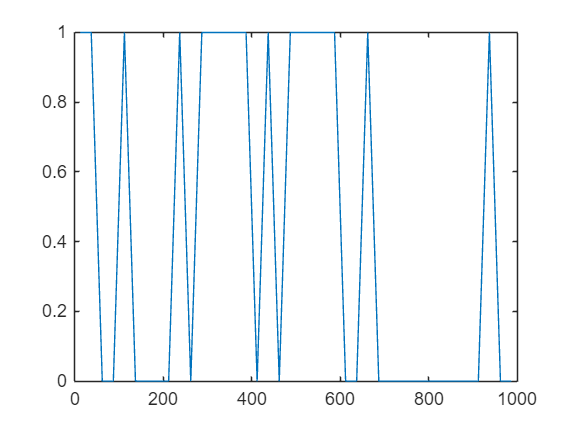

for i = 1:40
    [h(i), p(i)] = ttest2(DEV_F1_F2(:,i),STD_F1_F2(:,i));
end
figure
plot(SignificanceWindowTableSpikesAuditorySig.histcenters(1,[81:120]),h)

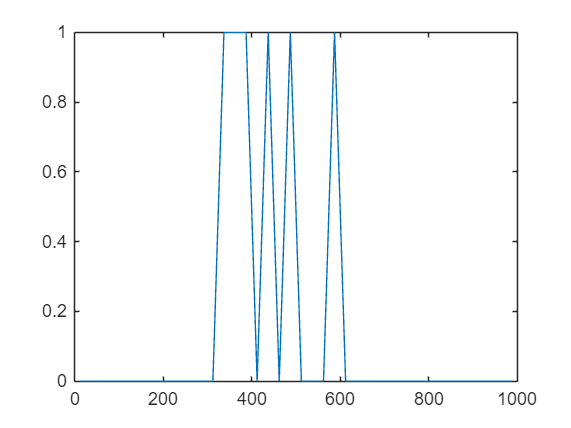

[c_pvalues, c_alpha, h, extra] = fdr_BH(p, 0.05);
figure
plot(SignificanceWindowTableSpikesAuditorySig.histcenters(1,[81:120]),h)

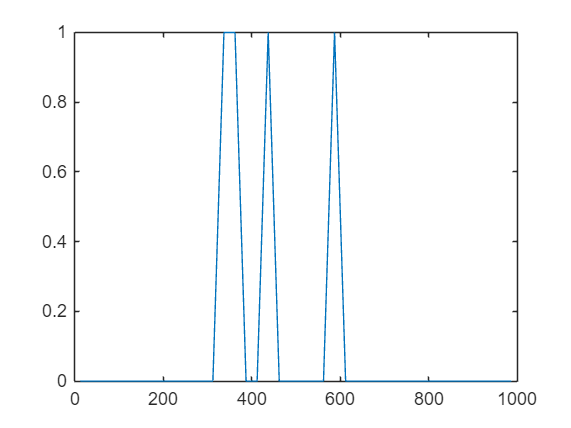

 [c_pvalues, c_alpha, h] = fwer_sidak(p, 0.05);
figure
plot(SignificanceWindowTableSpikesAuditorySig.histcenters(1,[81:120]),h)

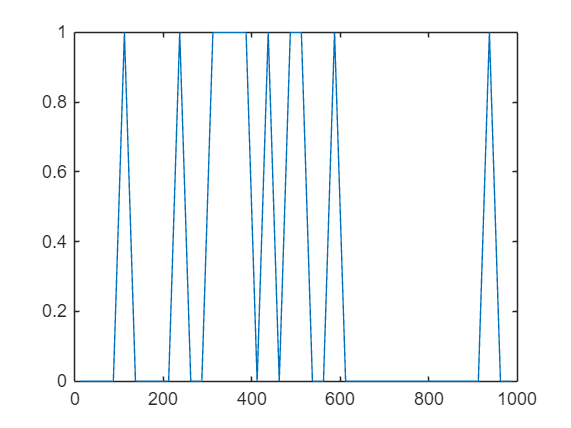

[c_pvalues, chi2_2k, h, extra] = mt_fisher(p, 0.01);
figure
plot(SignificanceWindowTableSpikesAuditorySig.histcenters(1,[81:120]),h)

[c_pvalues, ~, h] = fwer_holmbonf(p, 0.05);
figure
plot(SignificanceWindowTableSpikesAuditorySig.histcenters(1,[81:120]),h)

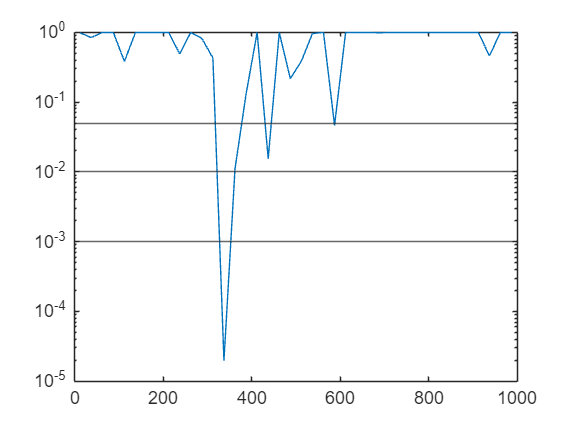

cd 'D:\Jazmin\MultichannelDataTanks\HIP'
% saveas(gcf,'h_DEV vs STD.pdf');
figure
plot(SignificanceWindowTableSpikesAuditorySig.histcenters(1,[81:120]),c_pvalues)
yline(0.05)
yline(0.01)
yline(0.001)
set(gca, 'YScale', 'log')

% saveas(gcf,'p_STD_CA1vsDG.pdf');

%Auditory and Significant
MeanSTD = mean(STD_F1_F2,"omitnan");
MeanDEV = mean(DEV_F1_F2,"omitnan");
MeanCTR = mean(CTR_F1_F2,"omitnan");
MMN = MeanDEV - MeanSTD;

SEM_STD = std(STD_F1_F2,"omitnan")./sqrt(length(STD_F1_F2));
SEM_DEV = std(DEV_F1_F2,"omitnan")./sqrt(length(DEV_F1_F2));
SEM_CTR = std(CTR_F1_F2,"omitnan")./sqrt(length(CTR_F1_F2));
SEM_MMN = SEM_DEV + SEM_STD;

% % CA1
% MeanSTD_CA1 = mean(STD_F1_F2_CA1,"omitnan");
% MeanDEV_CA1 = mean(DEV_F1_F2_CA1,"omitnan");
% MeanCTR_CA1 = mean(CTR_F1_F2_CA1,"omitnan");
% MMN = MeanDEV_CA1 - MeanSTD_CA1;
% % % MeanSTD_After = mean(STD_F1_F2_After,"omitnan");
% 
% SEM_STD_CA1 = std(STD_F1_F2_CA1,"omitnan")./sqrt(length(STD_F1_F2_CA1));
% SEM_DEV_CA1 = std(DEV_F1_F2_CA1,"omitnan")./sqrt(length(DEV_F1_F2_CA1));
% SEM_CTR_CA1 = std(CTR_F1_F2_CA1,"omitnan")./sqrt(length(CTR_F1_F2_CA1));
% SEM_MMN = SEM_DEV_CA1 + SEM_STD_CA1;
% 
% % % SEM_STD_After = std(STD_F1_F2_After,"omitnan")./sqrt(length(STD_F1_F2_After));

% %DG
% MeanSTD_DG = mean(STD_F1_F2_DG,"omitnan");
% MeanDEV_DG = mean(DEV_F1_F2_DG,"omitnan");
% MeanCTR_DG = mean(CTR_F1_F2_DG,"omitnan");
% MMN = MeanDEV_DG - MeanSTD_DG;
% % MeanSTD_After = mean(STD_F1_F2_After,"omitnan");
% 
% SEM_STD_DG = std(STD_F1_F2_DG,"omitnan")./sqrt(length(STD_F1_F2_DG));
% SEM_DEV_DG = std(DEV_F1_F2_DG,"omitnan")./sqrt(length(DEV_F1_F2_DG));
% SEM_CTR_DG = std(CTR_F1_F2_DG,"omitnan")./sqrt(length(CTR_F1_F2_DG));
% % SEM_STD_After = std(STD_F1_F2_After,"omitnan")./sqrt(length(STD_F1_F2_After));
% SEM_MMN = SEM_DEV_DG + SEM_STD_DG;

Baseline = mean(MeanSTD(4:8)) + std(MeanSTD(4:8),0,"all","omitnan")

Baseline = 0.5917

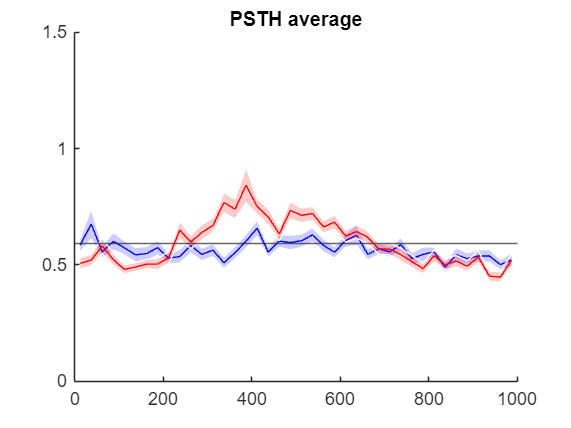

figure
% plot(histcenters, MeanSTD)
hold on
shadedErrorBar(SignificanceWindowTableSpikesAuditorySig.histcenters(1,[81:120]), MeanSTD,SEM_STD,'lineProps','b')
% shadedErrorBar(SignificanceWindowTableSpikesAuditorySig.histcenters(1,[81:120]), MeanSTD_DG,SEM_STD_DG,'lineProps','b')
% shadedErrorBar(SignificanceWindowTableSpikesAuditorySig.histcenters(1,[81:120]), MeanSTD_CA1,SEM_STD_CA1,'lineProps','b')
% hold on
shadedErrorBar(SignificanceWindowTableSpikesAuditorySig.histcenters(1,[81:120]), MeanDEV,SEM_DEV,'lineProps','r')
% shadedErrorBar(SignificanceWindowTableSpikesAuditorySig.histcenters(1,[81:120]), MeanDEV_CA1,SEM_DEV_CA1,'lineProps','r')
% shadedErrorBar(SignificanceWindowTableSpikesAuditorySig.histcenters(1,[81:120]), MeanDEV_DG,SEM_DEV_DG,'lineProps','r')
yline(Baseline)
ylim([0 1.5])
title('PSTH average')

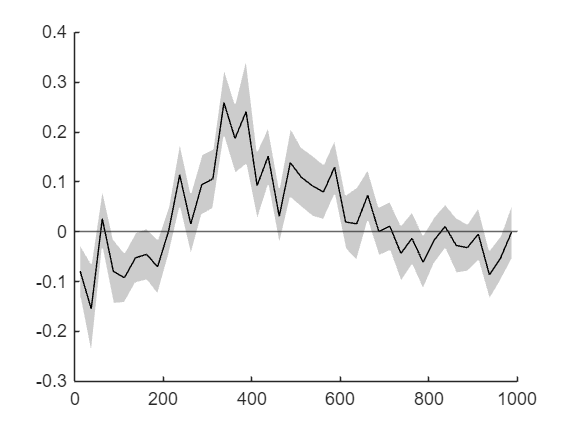

% 
% patch([-1000,-925,-925,-1000],[0,0,2.5,2.5],'blue','FaceAlpha',.3,'LineStyle','none')

figure
shadedErrorBar(SignificanceWindowTableSpikesAuditorySig.histcenters(1,[81:120]), MMN,SEM_MMN,'lineProps','k')
% patch([0,75,75,0],[0,0,1.5,1.5],"yellow",'FaceAlpha',.3,'LineStyle','none')
hold on
yline(0)

% patch([1000,1075,1075,1000],[0,0,2.5,2.5],'blue','FaceAlpha',.3,'LineStyle','none')
% 
% patch([2000,2075,2075,2000],[0,0,2.5,2.5],'blue','FaceAlpha',.3,'LineStyle','none')


% cd 'D:\Jazmin\MultichannelDataTanks\HIP\'
% saveas(gcf,'Gran_Average_longer_DG_DG_Sig_STD.pdf');
% saveas(gcf,'Gran_Average_longer_DG_DG_Sig_STD.tif');
% saveas(gcf,'Gran_Average_longer_DG_DG_Sig_STD.fig');
% % save('D:\Jazmin\MultichannelDataTanks\HIP\h_CA1_DG_Sig_STD.mat','h') 
% % save('D:\Jazmin\MultichannelDataTanks\HIP\p_CA1_DG_Sig_STD.mat','p') 